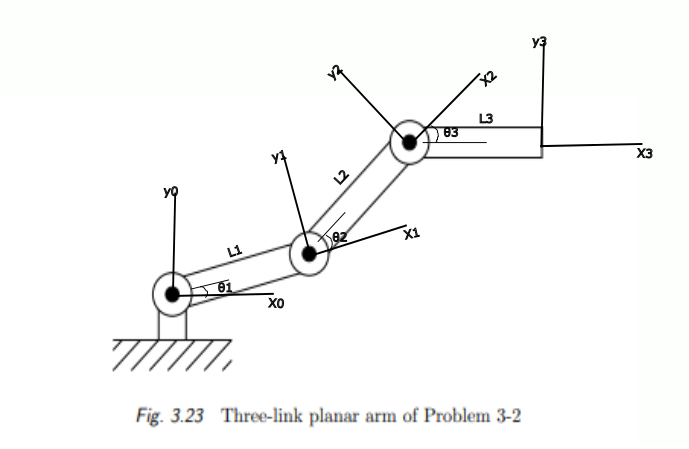

Problem 3-2 (No DH Parameters)

Because all the Z axes are out of the page, and all rotations are about the Z axis, then the translations can be found from simple trigonomtry, and the rotations are just Zaxis rotations. 

syms theta L L1 L2 L3 theta1 theta2 theta3
H_z = [cos(theta) -sin(theta) 0 0; sin(theta) cos(theta) 0 0; 0 0 1 0; 0 0 0 1]

$$H\_z = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_translation_L = [1 0 0 L*cos(theta); 0 1 0 L*sin(theta); 0 0 1 0; 0 0 0 1]

$$H\_translation\_L = \left(\begin{array}{cccc} 1 & 0 & 0 & L\,\cos\left(\theta \right)\\ 0 & 1 & 0 & L\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_generic = H_translation_L*H_z

$$H\_generic = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & L\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & L\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_0_1 = subs(subs(H_generic,L,L1),theta,theta1)

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & L_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & L_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_1_2 = subs(subs(H_generic,L,L2),theta,theta2)

$$H\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & L_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_2_3 = subs(subs(H_generic,L,L3),theta,theta3)

$$H\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_0_3 = H_0_1*H_1_2*H_2_3

$$H\_0\_3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{3}\right)\,\sigma_{3}-\sin\left(\theta_{3}\right)\,\sigma_{2} & 0 & L_{1}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sigma_{2}-L_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{3}+L_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-L_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{3}\right)\,\sigma_{3}+\sin\left(\theta_{3}\right)\,\sigma_{2} & \sigma_{1} & 0 & L_{1}\,\sin\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sigma_{3}+L_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{2}+L_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+L_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\sigma_{2}-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

Problem 3-5

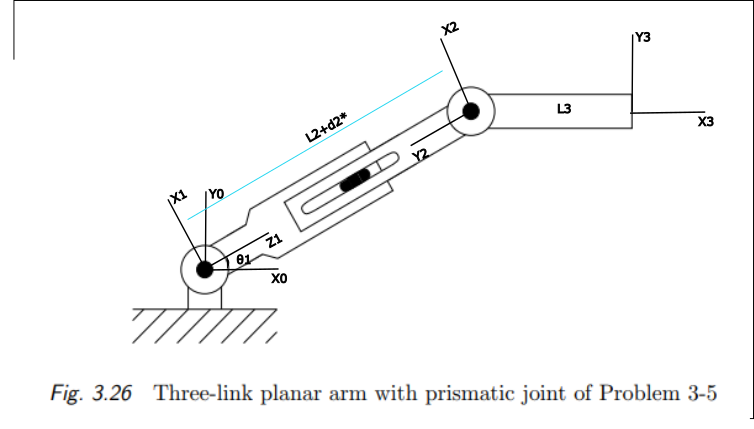

This also called for the forward kinematics to be determined, but we could use DH parameters. The trickiest part is that the Z axis has to point in the direction of the prismatic joint. The means that the Z axis has to change its orientation between each frame. However, once the DH parameters are determined the solution is easy to find. 

From the diagram I determined the following DH parameters

thetas = [theta1+90; 0; theta2-90];
ds = [0; d2+L2; 0];
as = [0; 0; L3];
alphas = [90; -90; 0];

t = table(thetas,ds,as,alphas)

t = 3×4 table
      thetas         ds       as    alphas
    ___________    _______    __    ______

    theta1 + 90    0          0       90  
    0              L2 + d2    0      -90  
    theta2 - 90    0          L3       0  


syms theta d a alpha theta1 theta2 d2 L2 L3

H = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
    0 sin(alpha) cos(alpha) d; 
    0 0 0 1]

$$H = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_0_1 = subs(subs(subs(subs(H,alpha,pi/2),a,0),d,0),theta, theta1+(pi/2))

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\frac{\pi }{2}\right) & 0 & \sin\left(\theta_{1}+\frac{\pi }{2}\right) & 0\\ \sin\left(\theta_{1}+\frac{\pi }{2}\right) & 0 & -\cos\left(\theta_{1}+\frac{\pi }{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_1_2 = subs(subs(subs(subs(H,alpha,-pi/2),a,0),d,L2+d2),theta, 0)

$$H\_1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & L_{2}+d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_2_3 = subs(subs(subs(subs(H,alpha,0),a,L3),d,0),theta, theta1-(pi/2))

$$H\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{1}-\frac{\pi }{2}\right) & -\sin\left(\theta_{1}-\frac{\pi }{2}\right) & 0 & L_{3}\,\cos\left(\theta_{1}-\frac{\pi }{2}\right)\\ \sin\left(\theta_{1}-\frac{\pi }{2}\right) & \cos\left(\theta_{1}-\frac{\pi }{2}\right) & 0 & L_{3}\,\sin\left(\theta_{1}-\frac{\pi }{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_0_3 = H_0_1*H_1_2*H_2_3

$$H\_0\_3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{5}\,\sigma_{2}-\sigma_{3}\,\sigma_{4} & 0 & \sigma_{2}\,\left(L_{2}+d_{2}\right)+L_{3}\,\sigma_{5}\,\sigma_{3}-L_{3}\,\sigma_{4}\,\sigma_{2}\\ \sigma_{5}\,\sigma_{2}+\sigma_{3}\,\sigma_{4} & \sigma_{1} & 0 & L_{3}\,\sigma_{5}\,\sigma_{2}-\sigma_{3}\,\left(L_{2}+d_{2}\right)+L_{3}\,\sigma_{3}\,\sigma_{4}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{5}\,\sigma_{3}-\sigma_{4}\,\sigma_{2}\\ \sigma_{2}=\sin\left(\theta_{1}+\frac{\pi }{2}\right)\\ \sigma_{3}=\cos\left(\theta_{1}+\frac{\pi }{2}\right)\\ \sigma_{4}=\sin\left(\theta_{1}-\frac{\pi }{2}\right)\\ \sigma_{5}=\cos\left(\theta_{1}-\frac{\pi }{2}\right) \end{array}$$